clc;
clear;
dsH=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Features\MONOTONICITY INDEX\Horizontal\Condition 3');
dsV=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Features\MONOTONICITY INDEX\Vertical\Condition 3');
Horizontal=table2array(readall(dsH));
Vertical=table2array(readall(dsV));
for i=1:28
    H(1,i)=mean(Horizontal(1:2,i));
end
for i=1:28
    V(1,i)=mean(Vertical(1:2,i));
end
X = categorical({'Mean','StandardDev','RMS','AbsMean','Skewness', ...
    'Kurtosis','Variance','MaxValue','MinValue','Peak2Peak','WaveformIndex','PeakIndex', ...
    'PulseIndex','MarginIndex','SkewnessIndex','KurtosisIndex','ProposedFeature1','ProposedFeature2','SpectralKurtosisMean','SpectralKurtosisStandardDeviation', ...
    'SpectralKurtosisSkewness','SpectralKurtosisKurtosis','SpectralEntropyMean','SpectralEntropyStandardDeviation', ...
    'SpectralEntropySkewness','SpectralEntropyKurtosis','SquareRootAmplitude','ProposedFeature3'});
X=reordercats(X,{'Mean','StandardDev','RMS','AbsMean','Skewness', ...
    'Kurtosis','Variance','MaxValue','MinValue','Peak2Peak','WaveformIndex','PeakIndex', ...
    'PulseIndex','MarginIndex','SkewnessIndex','KurtosisIndex','ProposedFeature1','ProposedFeature2','SpectralKurtosisMean','SpectralKurtosisStandardDeviation', ...
    'SpectralKurtosisSkewness','SpectralKurtosisKurtosis','SpectralEntropyMean','SpectralEntropyStandardDeviation', ...
    'SpectralEntropySkewness','SpectralEntropyKurtosis','SquareRootAmplitude','ProposedFeature3'})

X = 1×28 categorical array
     Mean      StandardDev      RMS      AbsMean      Skewness      Kurtosis      Variance      MaxValue      MinValue      Peak2Peak      WaveformIndex      PeakIndex      PulseIndex      MarginIndex      SkewnessIndex      KurtosisIndex      ProposedFeature1      ProposedFeature2      SpectralKurtosisMean      SpectralKurtosisStandardDeviation      SpectralKurtosisSkewness      SpectralKurtosisKurtosis      SpectralEntropyMean      SpectralEntropyStandardDeviation      SpectralEntropySkewness      SpectralEntropyKurtosis      SquareRootAmplitude      ProposedFeature3 


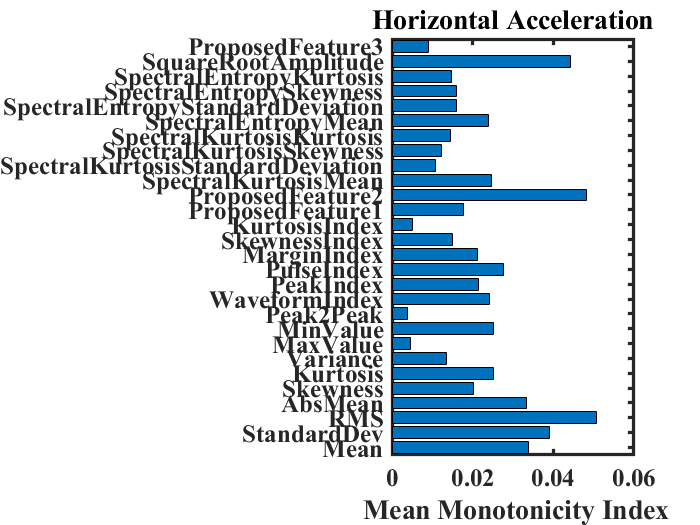


figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);
axes1 = axes('Parent',figure1);
hold(axes1,'on');
barh(X,H)
title('Horizontal Acceleration');  
box(axes1,'on');
hold(axes1,'off');
set(axes1,'FontName','Times New Roman','FontSize',15,'FontWeight','bold','LineWidth',2);
set(gcf,"visible",'on')
xlabel(' Mean Monotonicity Index','FontWeight','bold','FontName','Times New Roman'); 

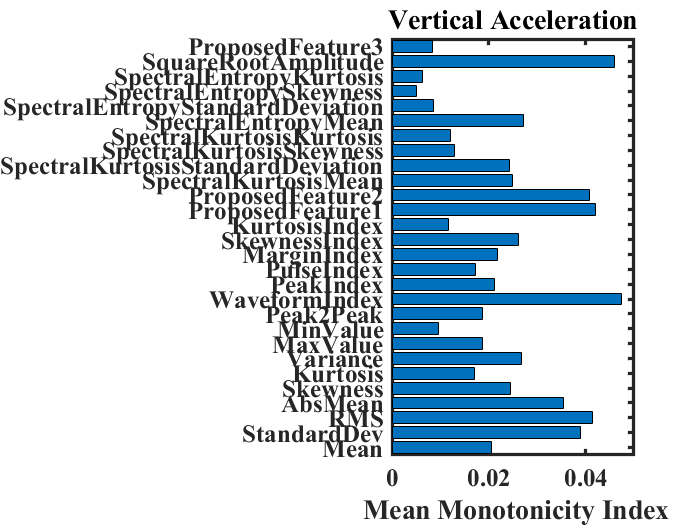


figure2 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);
axes2 = axes('Parent',figure2);
hold(axes2,'on');
barh(X,V)
title('Vertical Acceleration');  
box(axes2,'on');
hold(axes2,'off');
set(axes2,'FontName','Times New Roman','FontSize',15,'FontWeight','bold','LineWidth',2);
set(gcf,"visible",'on')
xlabel(' Mean Monotonicity Index','FontWeight','bold','FontName','Times New Roman');